%确定n
clc,clear
n = 6; 
m = 150000;
T1(1,[1:n])=37;
T2(1,[1:n])=37;
T3(1,[1:n])=37;
T4(1,[1:n])=37;
T5(1,[1:n])=37;
T1([1:m],1)=75;
T5([1:m],end)=37;

data = textread('data1.txt');
data(:,4) = data(:,4).*0.001;
houdu = [data(:,4);mean(data(:,4))*10];
alpha = data(:,3)./(data(:,2).*data(:,1));
alpha = [alpha;mean(alpha)*0.1];
h = 2000/m;
k = houdu./n;
r = alpha.*h./(k.^2);

format long
for i = 1:m
    %T1
    for j = 2:n-1
        T1(i+1,j) = (1-2*r(1)).*T1(i,j)+r(1).*(T1(i,j-1)+T1(i,j+1));
    end
    T1(i+1,n) = T1(i,n) + 2*r(1)*(T1(i,n-1)-T1(i,n))-(2*data(2,3)*h/(k(1)*k(2)*data(1,1)*data(1,2)))*(T2(i,1)-T2(i,2));
    %T2
    T2(i+1,1) = (1-2*r(2)).*T2(i,1)+r(2).*(T1(i,n)+T2(i,2));
    for j = 2:n-1
        T2(i+1,j) = (1-2*r(2)).*T2(i,j)+r(2).*(T2(i,j-1)+T2(i,j+1));
    end
    T2(i+1,n) = T2(i,n) + 2*r(2)*(T2(i,n-1)-T2(i,n))-(2*data(3,3)*h/(k(2)*k(3)*data(2,1)*data(2,2)))*(T3(i,1)-T3(i,2));
    %T3
    T3(i+1,1) = (1-2*r(3)).*T3(i,1)+r(3).*(T2(i,n)+T3(i,2));
    for j = 2:n-1
        T3(i+1,j) = (1-2*r(3)).*T3(i,j)+r(3).*(T3(i,j-1)+T3(i,j+1));
    end
    T3(i+1,n) = T3(i,n) + 2*r(3)*(T3(i,n-1)-T3(i,n))-(2*data(4,3)*h/(k(3)*k(4)*data(3,1)*data(3,2)))*(T4(i,1)-T4(i,2));
    %T4
    T4(i+1,1) = (1-2*r(4)).*T4(i,1)+r(4).*(T3(i,n)+T4(i,2));
    for j = 2:n-1
        T4(i+1,j) = (1-2*r(4)).*T4(i,j)+r(4).*(T4(i,j-1)+T4(i,j+1));
    end
    T4(i+1,n) = T4(i,n) + 2*r(4)*(T4(i,n-1)-T4(i,n))-(2*10*mean(data(:,4))/0.116115*h/(k(4)*k(5)*data(4,1)*data(4,2)))*(T5(i,1)-T5(i,2));
    %T5
    T5(i+1,1) = (1-2*r(5)).*T5(i,1)+r(5).*(T4(i,n)+T5(i,2));
    for j = 2:n-1
        T5(i+1,j) = (1-2*r(5)).*T5(i,j)+r(5).*(T5(i,j-1)+T5(i,j+1));
    end
end

T_out_10 = T4(:,6);
save('T_out_10.mat','T_out_10')

T = [T1,T2,T3,T4,T5];
T_choice = [T(1,:)]

T_choice =     75    37    37    37    37    37    37    37    37    37    37    37    37    37    37    37    37    37    37    37    37    37    37    37    37    37    37    37    37    37


for i = 75:75:150001
    T_choice=[T_choice;T(i,:)];
end    


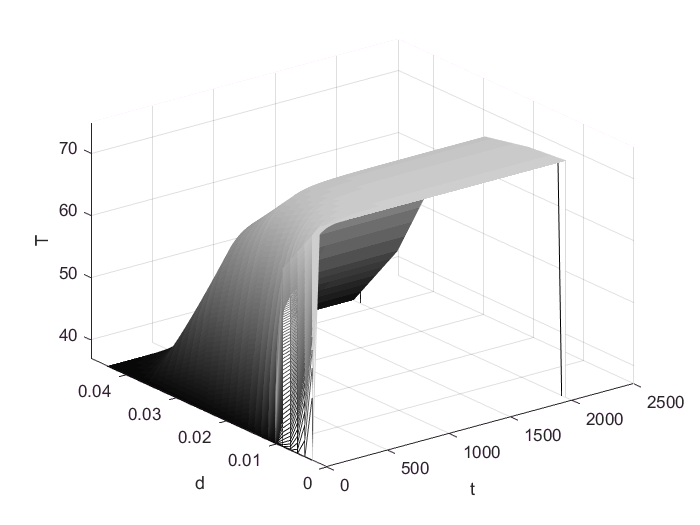

time = h.*[1:m+1];
jiange = sum(houdu)./(5*n);
jiange = repmat(jiange,1,5*n);
jiange = cumsum(jiange);
[x,y] = meshgrid(time,jiange);
i = mesh(x,y,T');colormap gray
xlabel('t');ylabel('d');zlabel('T');
axis([0,2500,0,0.047,37,75])
caxis([35,85])

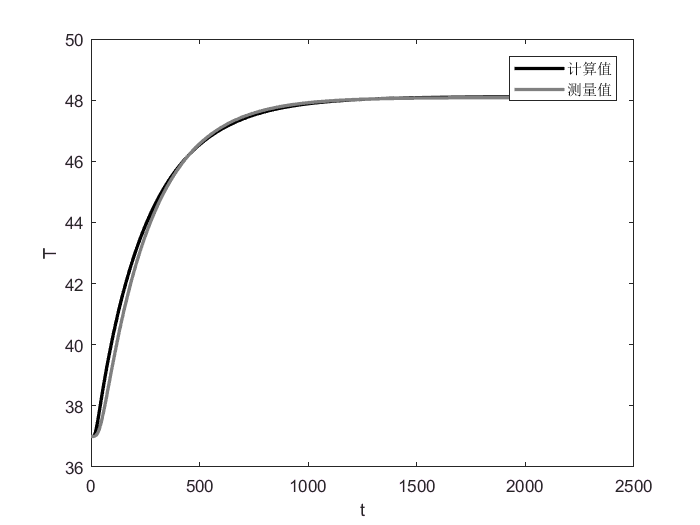

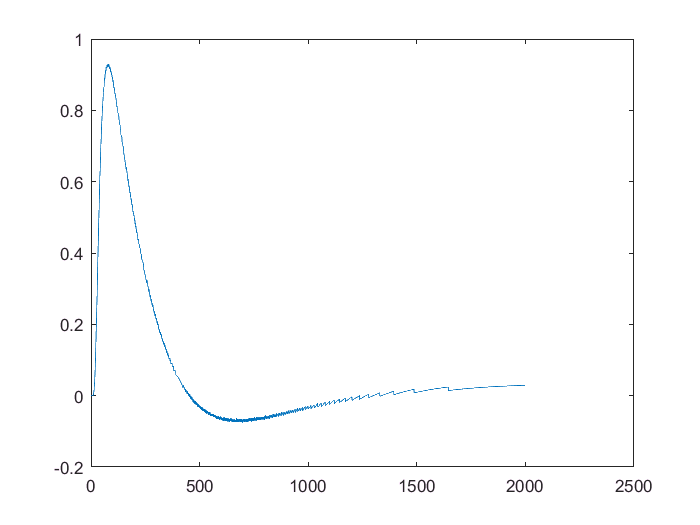

sample = textread('data3.txt');
Ttest = [time',T(:,n*4)];
plot(Ttest(:,1),Ttest(:,2),'k','linewidth',2);
hold on
plot(sample(:,1),sample(:,2),'linewidth',2,'color',[.5 .5 .5])
hold off
legend('计算值','测量值')
xlabel('t')
ylabel('T')

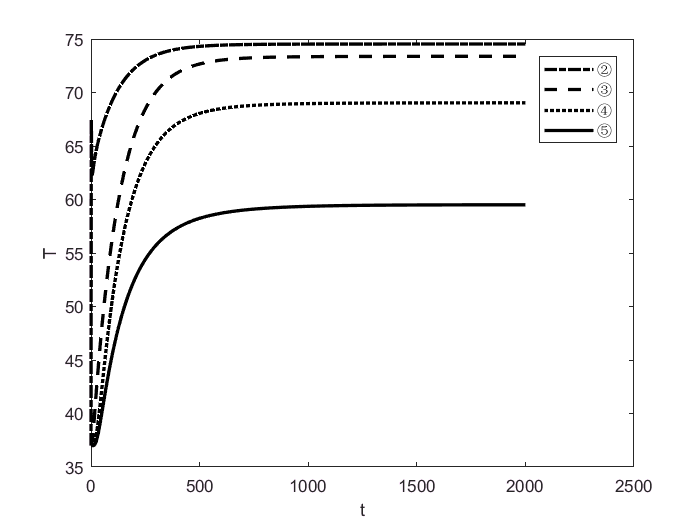

plot(time',T(:,5),'-.k','linewidth',2)
hold on
plot(time',T(:,10),'--k','linewidth',2)
plot(time',T(:,15),':k','linewidth',2)
plot(time',T(:,20),'k','linewidth',2)
hold off
axis([0,2500,35,75]);
legend('②','③','④','⑤')
xlabel('t')
ylabel('T')

colormap gray